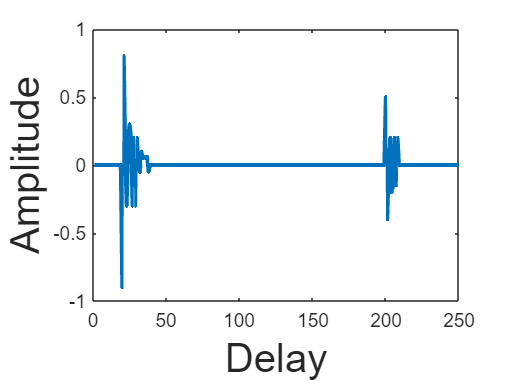

clc;
clear all;
close all;
RUNS=200;
Iterations=5000;
N=256;
u=5e-3;
rhozA=2.5e-6;
rhoRZA=1e-5;
eps=10;
MSE=zeros(RUNS,Iterations);
ZAMSE=zeros(RUNS,Iterations);
RZAMSE=zeros(RUNS,Iterations);
wopt=zeros(1,N);
wopt(1,20:38)=[-0.9,0.8,0.1,-0.3,0.2,0.3,0.2,-0.3,0.2,-0.3,0.2,0,-0.05,0.1,0.05,0.06,0.05,0.06,-0.05];
wopt(1,200:208)=[0.5,-0.4,0,0.2,-0.2,-0.15,0.2,-0.15,0.2];
wopt=wopt';
plot(wopt,"LineWidth",2)
xlabel("Delay","FontSize",20)
ylabel("Amplitude","FontSize",20)

ylim([-1 1])
xlim([0 250])

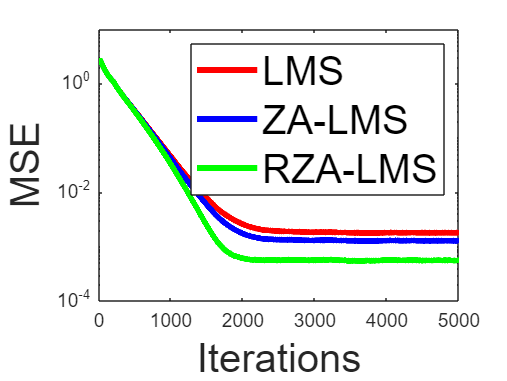

for i=1:RUNS
    ws=zeros(N,1);
    wZA=zeros(N,1);
    wRZA=zeros(N,1);
    for j=1:Iterations
       xn(j)=randn(1,1);
       v=randn(1,1)*sqrt(0.001);
       if j<=N
       x=[flip(xn(1,1:j)) zeros(1,N-j)]';
       else
       x=[flip(xn(1,j-N+1:j)) zeros(1,N-j)]';
       end
       y=wopt'*x+v;
       e=y-(ws'*x);
       ws=ws+(u*e*x);
       MSE(i,j)=norm(wopt-ws)^2;
       e=y-(wZA'*x);
       wZA=wZA+(u*e*x)-(rhozA*sign(wZA));
       ZAMSE(i,j)=norm(wopt-wZA)^2;
       e=y-(wRZA'*x);
       wRZA=wRZA+(u*e*x)-((rhoRZA*sign(wRZA))./(1+eps*abs(wRZA)));
       RZAMSE(i,j)=norm(wopt-wRZA)^2;

    end
end
NMSE=sum(MSE,1)/RUNS;
ZANMSE=sum(ZAMSE,1)/RUNS;
RZANMSE=sum(RZAMSE,1)/RUNS;
semilogy(1:Iterations,NMSE,'r-',1:Iterations,ZANMSE,'b-',1:Iterations,RZANMSE,'g-',"LineWidth",3)
legend("LMS","ZA-LMS","RZA-LMS","FontSize",20)
xlabel("Iterations","FontSize",20);
ylabel("MSE","FontSize",20);